## Boas Práticas

clear all;
close all
clc;

%load('Voz.mat') 

## Leitura do arquivo .wav - audioread


[Y, FS] = audioread('Audio02.wav')

Y =    -0.0022
   -0.0021
   -0.0019
   -0.0018
   -0.0018
   -0.0017
   -0.0017
   -0.0019
   -0.0020
   -0.0021


FS = 44100

% load('Voz.mat')
% Y é a amplitude, e FS é a frequencia do sinal lido

% TS = tempo entre dois pontos
TS = 1/FS

TS = 2.2676e-05

% Npontos = quantidade de pontos gravados
Npontos = length(Y);
% Vfinal é o tempo do audio
Vfinal = (Npontos-1)*TS

Vfinal = 8.0035

% Vetor tempo usado para plots
tempo = linspace(0,Vfinal,Npontos)

tempo =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


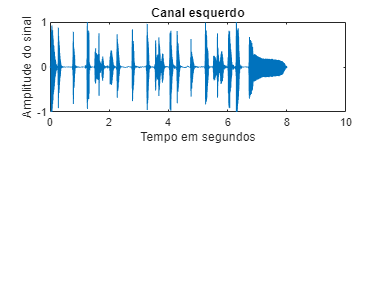


figure(1);

subplot(2,1,1)
plot(tempo, Y(:,1))
xlabel("Tempo em segundos")
ylabel("Amplitude do sinal")
title("Canal esquerdo")

% subplot(2,1,2)
% plot(tempo, Y(:,2))
% xlabel("Tempo em segundos")
% ylabel("Amplitude od sinal")
% title("Canal Direito")

## Ouvir um arquivo .wav

%sound(Y,FS);

## FFT


FY = fftshift(fft(Y));

## Visualizar o FFT

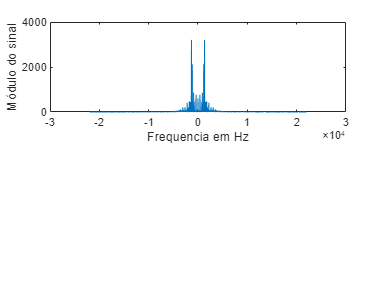

frequencia = linspace(-FS/2,FS/2,Npontos);

figure(2)

subplot(2,1,1)
plot(frequencia,abs(FY(:,1)))
xlabel("Frequencia em Hz")
ylabel("Módulo do sinal")

% title("Canal esquerdo")

% subplot(2,1,2)
% plot(frequencia,angle(FY(:,1)))
% xlabel("Frequencia em Hz")
% ylabel("Fase do sinal")
% title("Canal esquerdo")

% subplot(2,1,1)
% xlim([-3000, 3000])
% ylim([24 7400])
% plot(t)
% plot(time)
% TS = t(800)/800;
% FS = 1/TS

## PF me da um tiro